Fmax = 5500;
Lopt = 0.055;
Arel = 0.3;
Brel = 3.6;
Fiso = 0.9;
q = 0.5;
Fcc = Fmax*Fiso*q;
fac = min(1, 3.33*q);
F = Fiso*q*Fmax*(0:100)/100;
Vcc = fac*Lopt*Brel*(1-Fmax*q*(Fiso+Arel)./(F+Arel*Fmax*q));
aveP = fac*Lopt*Brel*q*Fmax*Fiso*(1/2+Arel/Fiso-Arel*(Fiso+Arel)*reallog(1+Fiso/Arel)/Fiso^2)

aveP = 106.4401


Vcc_arr(2:10) = -interp1([0,9],[0,aveP*10/9],1:9)./F(2:10);
Vcc_arr(1) = Vcc_arr(2);
Vcc_arr(11:90) = -(aveP*10/9)./F(11:90);
Vcc_arr(91:101) = -interp1([90,100],[aveP*10/9,0],90:100)./F(91:101);
P_arr = -Vcc_arr.*F;
aveP_arr = mean(P_arr(1:101))

aveP_arr = 105.9717

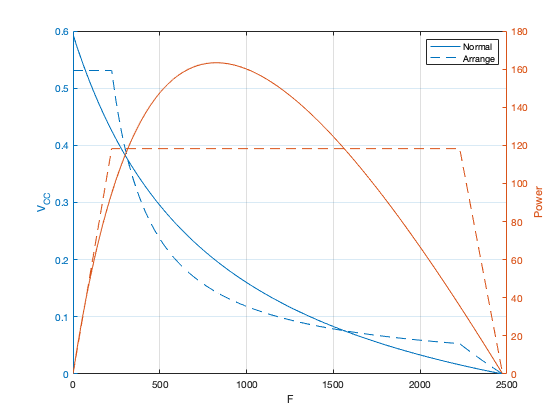


yyaxis left
plot(F,-Vcc)
hold on
plot(F, -Vcc_arr)
ylabel('V_{CC}')
yyaxis right
plot(F,-Vcc.*F)
hold on
plot(F,-Vcc_arr.*F)
ylabel('Power')
xlabel('F')
grid on
legend('Normal', 'Arrange')